# **PV**

## GLOBULOS BLANCOS

### a) Anotaciones

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_PvTk\PvTk1'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.jpg'));

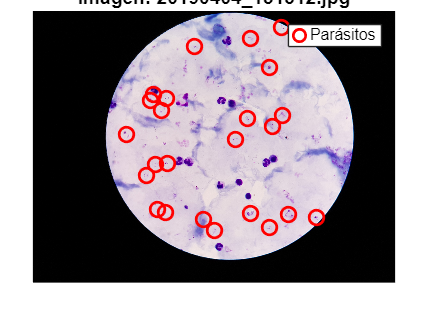

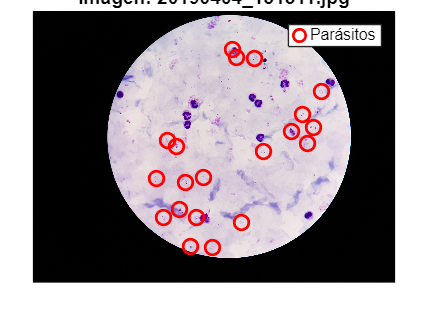

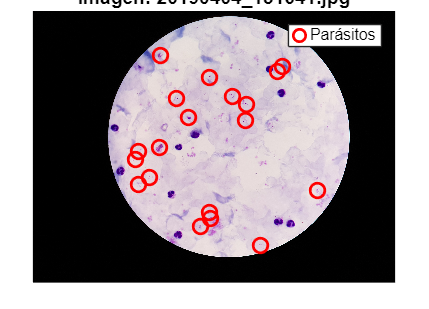

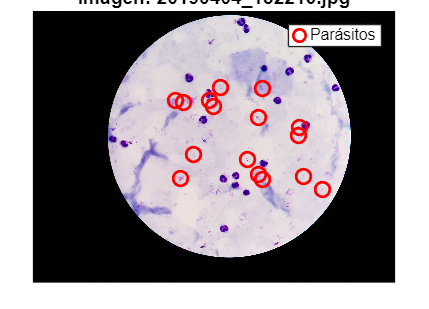

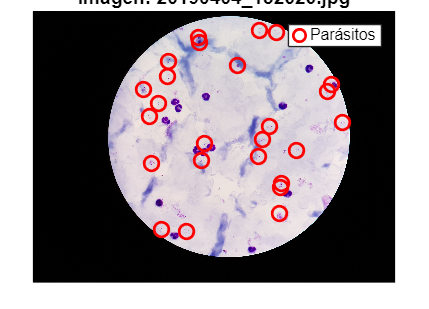

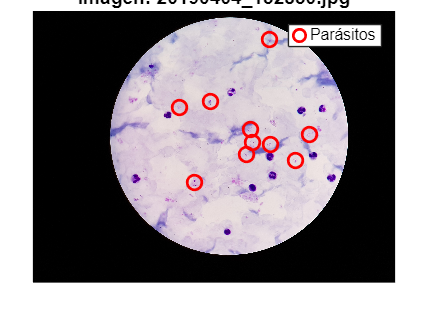

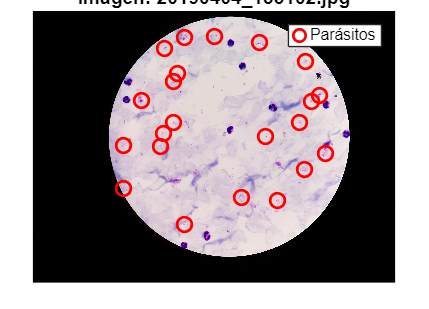

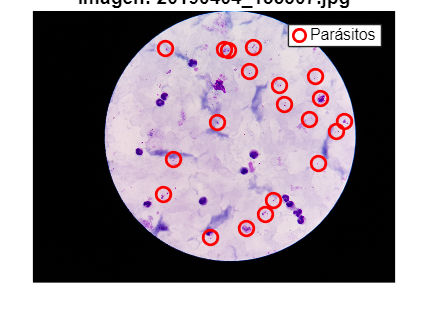

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_annotations\PvTk1', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasitized'), :);
    x_parasitos = (solo_parasitos.Var6);
    y_parasitos = (solo_parasitos.Var7);
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
    
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('Parásitos');
    hold off;
end

## PARASITOS

### b) 2º Modelo Otsu

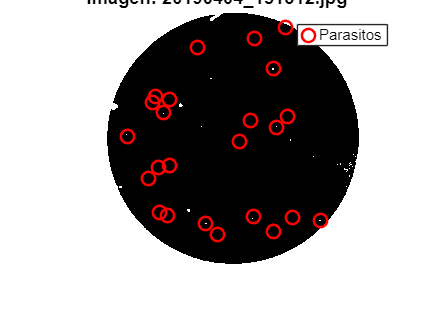

numero_de_parasitos = 24

candidatos_a_parasitos = 77

parasitos_detectados = 20

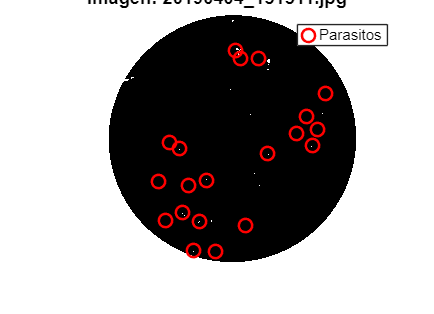

numero_de_parasitos = 20

candidatos_a_parasitos = 63

parasitos_detectados = 16

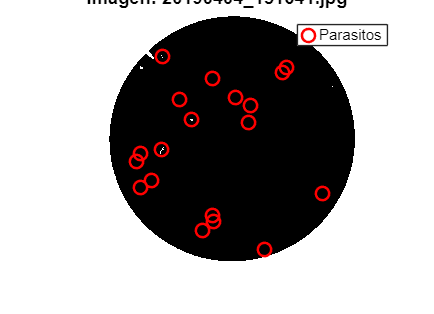

numero_de_parasitos = 19

candidatos_a_parasitos = 34

parasitos_detectados = 16

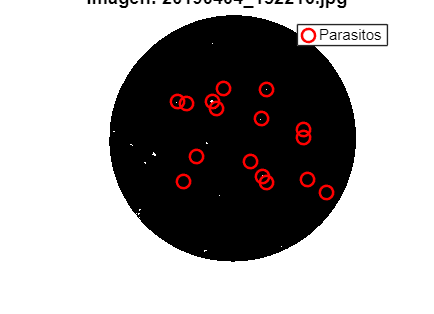

numero_de_parasitos = 16

candidatos_a_parasitos = 47

parasitos_detectados = 12

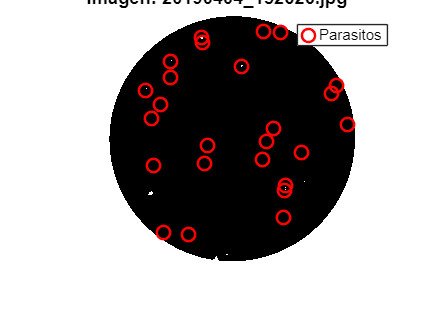

numero_de_parasitos = 25

candidatos_a_parasitos = 39

parasitos_detectados = 15

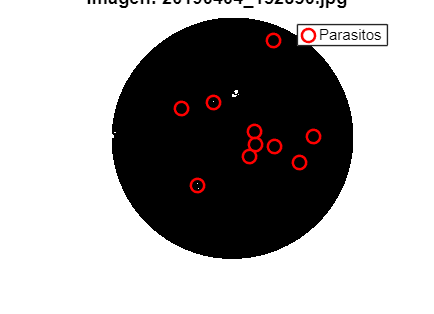

numero_de_parasitos = 10

candidatos_a_parasitos = 27

parasitos_detectados = 5

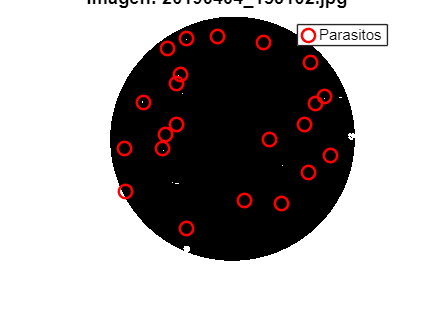

numero_de_parasitos = 22

candidatos_a_parasitos = 39

parasitos_detectados = 14

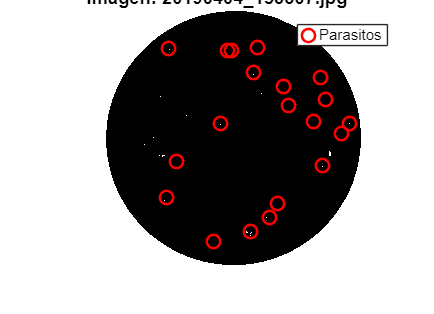

numero_de_parasitos = 20

candidatos_a_parasitos = 60

parasitos_detectados = 19

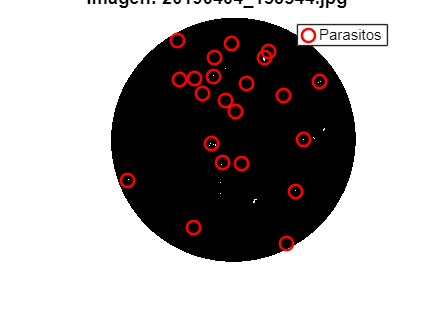

numero_de_parasitos = 22

candidatos_a_parasitos = 70

parasitos_detectados = 20

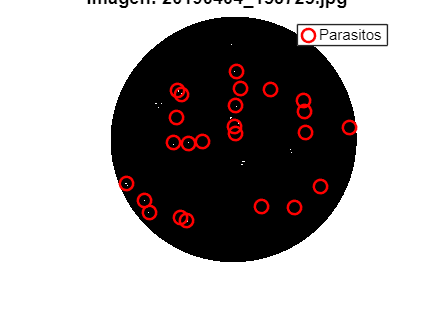

numero_de_parasitos = 24

candidatos_a_parasitos = 59

parasitos_detectados = 24

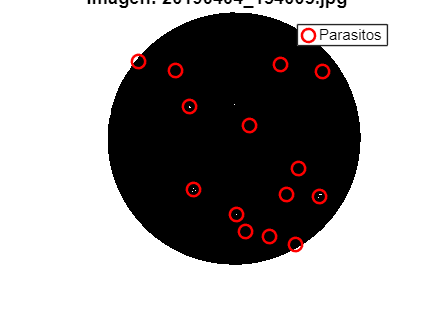

numero_de_parasitos = 14

candidatos_a_parasitos = 26

parasitos_detectados = 12

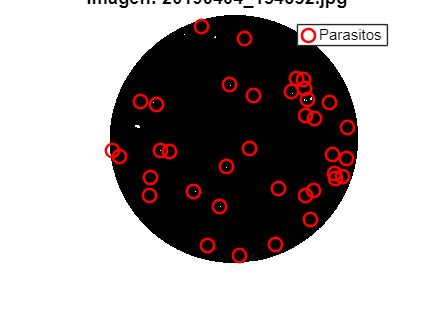

numero_de_parasitos = 37

candidatos_a_parasitos = 45

parasitos_detectados = 22

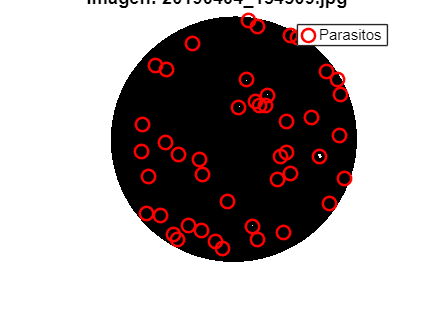

numero_de_parasitos = 45

candidatos_a_parasitos = 45

parasitos_detectados = 34

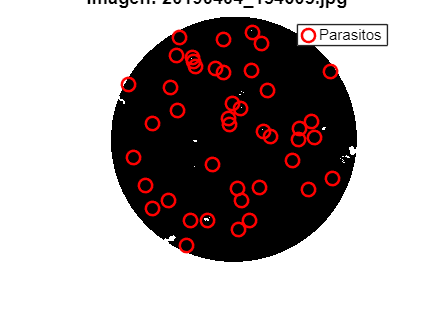

numero_de_parasitos = 43

candidatos_a_parasitos = 71

parasitos_detectados = 34

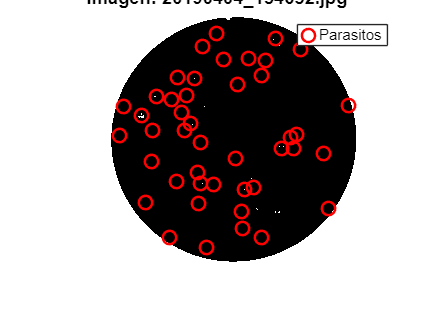

numero_de_parasitos = 44

candidatos_a_parasitos = 62

parasitos_detectados = 31

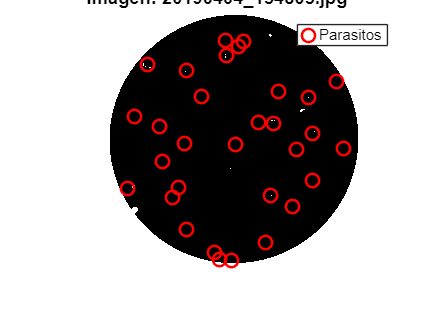

numero_de_parasitos = 31

candidatos_a_parasitos = 44

parasitos_detectados = 22

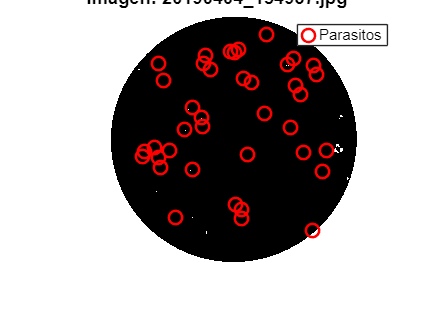

numero_de_parasitos = 39

candidatos_a_parasitos = 52

parasitos_detectados = 23

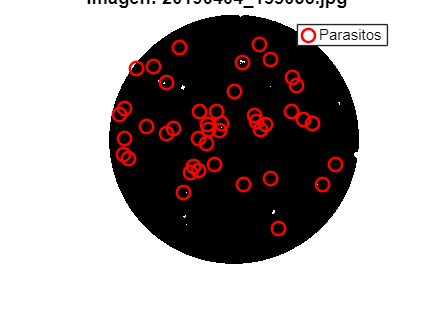

numero_de_parasitos = 43

candidatos_a_parasitos = 50

parasitos_detectados = 18

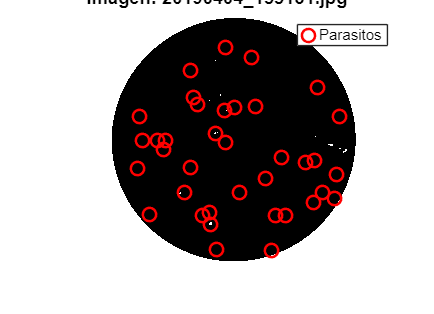

numero_de_parasitos = 37

candidatos_a_parasitos = 56

parasitos_detectados = 15

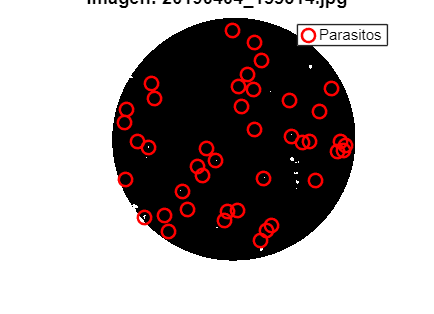

numero_de_parasitos = 42

candidatos_a_parasitos = 45

parasitos_detectados = 24

total_parasitos_reales = 0;
total_candidatos = 0;
total_parasitos_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    
    % Binario y escala de grises
    I_gray=im2double(rgb2gray(I));
    
    % 1. Filtro
    I_sinruido=medfilt2(I_gray, [3 3]);

    % 2. Umbral
    threshold = graythresh(I_sinruido)*0.95;

    % 3. Binarizar
    M1 = imbinarize(I_sinruido, threshold);

    % 4. Tener el negativo
    negativo= imcomplement(M1);

    % 5. Rellenar agujeros
    M2 = imfill(M1, 'holes');

    % 6. Separar WBCs
    WBC_mask_ruido = M2 & ~M1;

    % 7. Eliminar pequeños ruidos
    WBC_mask = bwareaopen(WBC_mask_ruido, 1500);

    % 8. Parasitos que se detecta
    parasitos= negativo-WBC_mask;
    
    % Visualiza la máscara final
    figure;
    imshow(parasitos);hold on;
    
    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_annotations\PvTk1', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasitized'), :);
    x_parasitos = (solo_parasitos.Var6);
    y_parasitos = (solo_parasitos.Var7);
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
   
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('Parasitos');
    hold off;
    % ============Verificar el modelo========
    
    % Extraer el numero de parasitos
    tamano=size(solo_parasitos);
    numero_de_parasitos = tamano(1,1)

    % Candidatos a parasitos
    n=8;
    CC_2 = bwconncomp(parasitos,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_parasitos=tamano(1,1)

    % Parasitos detectados
    umbral_distancia = 50;
    parasitos_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada parásito real
    for p = 1:length(x_parasitos)
        centro_real = [x_parasitos(p), y_parasitos(p)];
        for d = 1:length(caracteristicas)
            if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                parasitos_detectados = parasitos_detectados + 1;
                detectados_usados(d) = true;
                break;  % Evita contar un parásito detectado más de una vez
            end
        end
    end
    % Mostrar parasitos detectados
    parasitos_detectados

    % Sumas de los parasitos reales, candidatos y detectados 
    total_parasitos_reales = total_parasitos_reales + numero_de_parasitos;
    total_candidatos = total_candidatos + candidatos_a_parasitos;
    total_parasitos_detectados = total_parasitos_detectados + parasitos_detectados;
end

% Ananlizar modelo con estos resultados
total_parasitos_reales

total_parasitos_reales = 577

total_candidatos

total_candidatos = 1011

total_parasitos_detectados

total_parasitos_detectados = 396


% Confusion matrix
TP=total_parasitos_detectados;
FP=total_candidatos-total_parasitos_detectados;
FN=total_parasitos_reales-total_parasitos_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 68.6308

precision=(TP/(TP+FP))*100

precision = 39.1691